clear all; close all;

## Params

a = 100 % Edge Length

a = 100

N = 20 % Number of LED's per segment

N = 20

## Calculate Corners

phi = (1 + sqrt(5))/2

phi = 1.6180

scale = (a * phi) / 2

scale = 80.9017


corners = [
% Orange    
1 1 1 % 1
1 1 -1
1 -1 1
1 -1 -1
-1 1 1
-1 1 -1
-1 -1 1
-1 -1 -1
% Green
0        phi    1/phi % 9
0        phi   -1/phi
0       -phi    1/phi
0       -phi   -1/phi
% Blue
 1/phi  0       phi % 13
 1/phi  0      -phi
-1/phi  0       phi
-1/phi  0      -phi
% Pink
 phi     1/phi  0 % 17
 phi    -1/phi  0
-phi     1/phi  0
-phi    -1/phi  0
];

corners = corners * scale;

## define edges

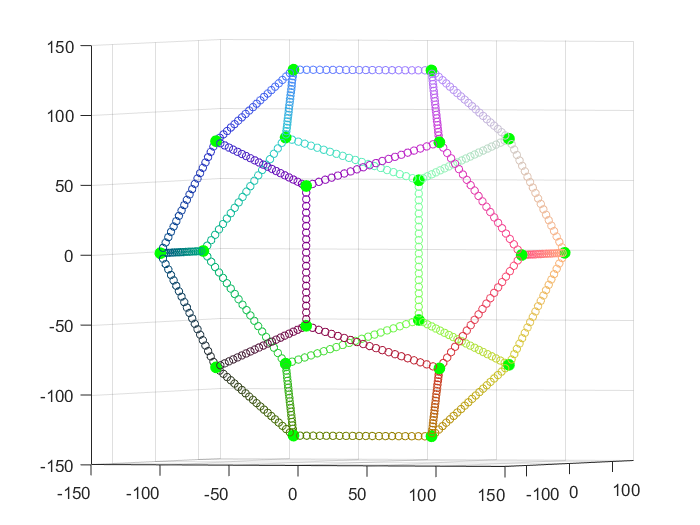

edgeCorners = [
% Lower V
14 16
16 8
8 12
12 4
4 14
16 6
6 10
10 2
2 14
%Standoffs
2 17
4 18
12 11
8 20
6 19
10 9
%Upper Ring
9 1
1 17
17 18
18 3
3 11
11 7
7 20
20 19
19 5
5 9
%Roof
1 13
3 13
7 15
5 15
15 13
];

leds = [];
t = linspace(0, 1, N+2);
for i=1:length(edgeCorners)    
    fullEdgeLeds = interp1([0 1], [corners(edgeCorners(i,1),:); corners(edgeCorners(i,2),:)] ,t);
    leds = [leds ; fullEdgeLeds(2:N+1,:)];
end



scatter3(corners(:,1), corners(:,2), corners(:,3), 50, 'green', "filled");
hold on;
scatter3(leds(:,1), leds(:,2), leds(:,3),20, [rescale(leds(:,1),0,1), rescale(leds(:,2),0,1), rescale(leds(:,3),0,1)] );
xlim([-150 150]); ylim([-150 150]); zlim([-150 150]); 
view([16 11]);

hold off;

Rotate around Y axis, to stand it up to a corner

alpha = acos(sqrt((5-sqrt(5))/10))/2 % angle to turn it by

alpha = 0.5086

alpha_d = rad2deg(alpha)

alpha_d = 29.1413


R = [cos(alpha)  0 sin(alpha)
      0           1 0 
      -sin(alpha) 0 cos(alpha)]

R =     0.8734         0    0.4870
         0    1.0000         0
   -0.4870         0    0.8734


Ry = transpose(R * transpose(corners)) 

Ry =   110.0576   80.9017   31.2650
   31.2650   80.9017 -110.0576
  110.0576  -80.9017   31.2650
   31.2650  -80.9017 -110.0576
  -31.2650   80.9017  110.0576
 -110.0576   80.9017  -31.2650
  -31.2650  -80.9017  110.0576
 -110.0576  -80.9017  -31.2650
   24.3482  130.9017   43.6711
  -24.3482  130.9017  -43.6711


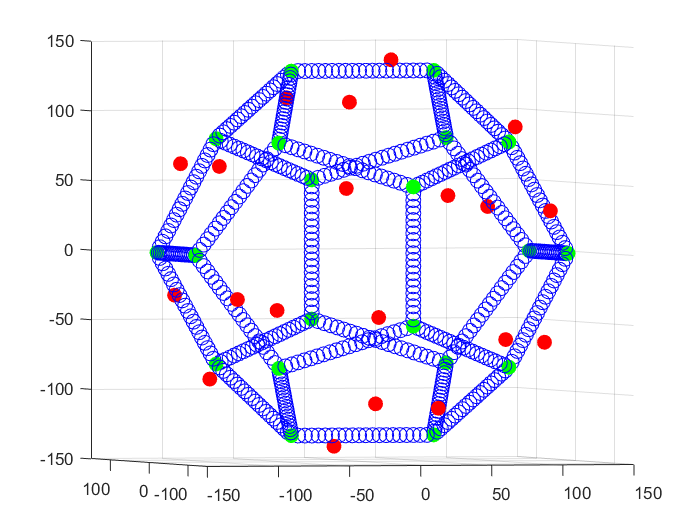


t = 100;
r = linspace(0, 1, 100);
ticks = linspace(0, 1, 6);
scatter3(corners(:,1), corners(:,2), corners(:,3), 80, 'green', "filled");
hold on;
scatter3(Ry(:,1), Ry(:,2), Ry(:,3), 80, 'Red', "filled");
scatter3(leds(:,1), leds(:,2), leds(:,3), 80, 'blue');

xlim([-150 150]); ylim([-150 150]); zlim([-150 150]); 



for i=1:t
    color = [r(i) 0 0];
    plot = scatter3(corners(:,1), corners(:,2), corners(:,3), 80, color, "filled");
    %xticks(ticks); yticks(ticks); zticks(ticks);
    view(20 + 0.5*i, 24);
    grid minor;
    drawnow
    pause(0.01);
end


